# Full Injector Simulation

## Flow Characteristics

clear;

chamberPressure = 22.4*10^5; %         Pa         Chamber pressure

ox.mDot = 2.202; %                      kg/s          Fuel mass flow rate 
fu.mDot = 1.028; %                      kg/s          Oxidizer mass flow rate
filmCoolingPercent = .05;

co.mDot = filmCoolingPercent*(ox.mDot + fu.mDot);
fu.mDot = fu.mDot - co.mDot;

ox.N_orifices = 30; %                 -          Number of oxidizer orifices
fu.N_orifices = 30; %                 -          Number of fuel orifices
co.N_orifices = 8;

ox.rho = 780; %                       kg/m^3     Oxidizer density
fu.rho = 789; %                       kg/m^3     Fuel density
co.rho = fu.rho;

ox.C_d = 0.25; %                       -          Oxidizer discharge coefficient
fu.C_d = 0.3; %                       -          Fuel discharge coefficient
co.C_d = .6;

ox.deltaP = 22.13*10^5; %                bar       Oxidizer pressure difference
fu.deltaP = 22.13*10^5; %                bar       Fuel pressure difference
co.deltaP = fu.deltaP;

ox.stiffness = ox.deltaP/chamberPressure;
fu.stiffness = fu.deltaP/chamberPressure;

ox.flow = getFlow(ox); % Gets flow data for oxidizer
fu.flow = getFlow(fu); % Gets flow data for fuel
co.flow = getFlow(co);

centralMixtureRatio = ox.mDot/fu.mDot;
totalMixtureRatio   = ox.mDot/(fu.mDot + co.mDot);

fprintf('Oxidizer Passage Diameter:\t\t %.4f in', ox.flow.d*100/2.54);

Oxidizer Passage Diameter:		 0.0993 in

fprintf('Oxidizer Passage Area:    \t\t %.4f in^2', ox.flow.A*(100/2.54)^2);

Oxidizer Passage Area:    		 0.0077 in^2

fprintf('Oxidizer Volume Flow Rate:\t\t %.4f m^3/s', ox.flow.Q);

Oxidizer Volume Flow Rate:		 0.0028 m^3/s

fprintf('Oxidizer Exit Velocity:   \t\t %.3f m/s', ox.flow.v);

Oxidizer Exit Velocity:   		 18.832 m/s

fprintf('Oxidizer Stiffness:       \t\t %.3f %%', ox.stiffness*100);

Oxidizer Stiffness:       		 98.795 %


fprintf('Fuel Passage Diameter:    \t\t %.4f in', fu.flow.d*100/2.54);

Fuel Passage Diameter:    		 0.0567 in

fprintf('Fuel Passage Area:        \t\t %.4f in^2', fu.flow.A*(100/2.54)^2);

Fuel Passage Area:        		 0.0025 in^2

fprintf('Fuel Volume Flow Rate:    \t\t %.4f m^3/s', fu.flow.Q);

Fuel Volume Flow Rate:    		 0.0011 m^3/s

fprintf('Fuel Exit Velocity:       \t\t %.3f m/s', fu.flow.v);

Fuel Exit Velocity:       		 22.469 m/s

fprintf('Fuel Stiffness:           \t\t %.3f %%', fu.stiffness*100);

Fuel Stiffness:           		 98.795 %


fprintf('Coolant Passage Diameter: \t\t %.4f in', co.flow.d*100/2.54);

Coolant Passage Diameter: 		 0.0335 in

fprintf('Coolant Passage Area:     \t\t %.4f in^2', co.flow.A*(100/2.54)^2);

Coolant Passage Area:     		 0.0009 in^2

fprintf('Coolant Volume Flow Rate: \t\t %.4f m^3/s', co.flow.Q);

Coolant Volume Flow Rate: 		 0.0002 m^3/s

fprintf('Coolant Exit Velocity:    \t\t %.3f m/s', co.flow.v);

Coolant Exit Velocity:    		 44.938 m/s


fprintf('Orifice Diameter Ratio:   \t\t %.2f', ox.flow.d/fu.flow.d);

Orifice Diameter Ratio:   		 1.75


fprintf('Central Mixture Ratio:    \t\t %.3f', centralMixtureRatio);

Central Mixture Ratio:    		 2.541

fprintf('Total Mixture Ratio:      \t\t %.3f', totalMixtureRatio);

Total Mixture Ratio:      		 2.142

## Impingement Angle

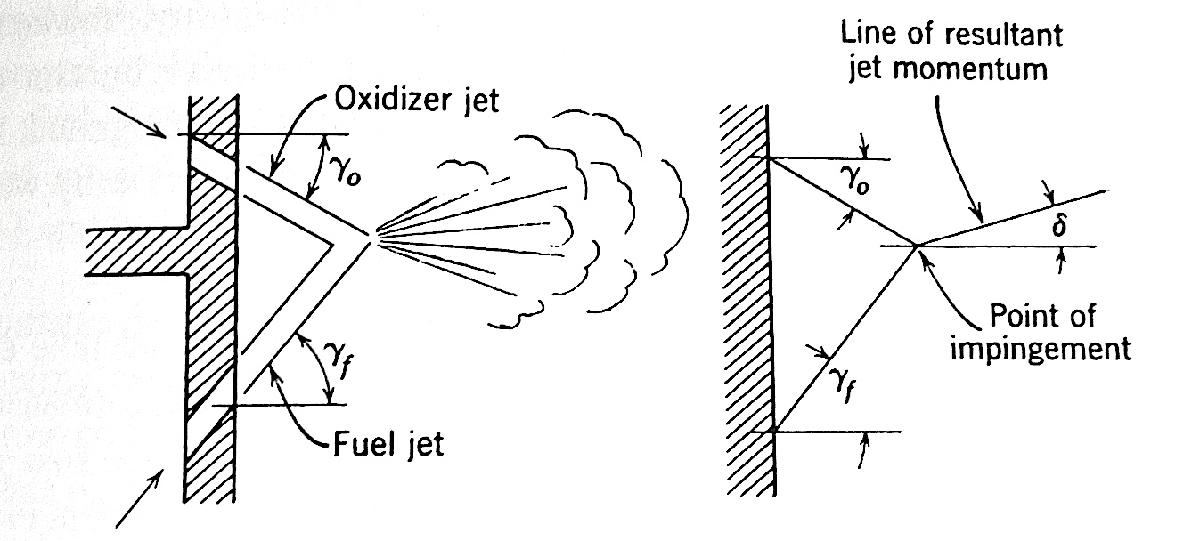

ox.gamma = 5;
fu.gamma = 55;

alpha = ox.gamma + fu.gamma; % Convergence angle

tand = (ox.mDot*ox.flow.v*sind(ox.gamma) - fu.mDot*fu.flow.v*sind(fu.gamma))...
    / (ox.mDot*ox.flow.v*cosd(ox.gamma) + fu.mDot*fu.flow.v*cosd(fu.gamma));
delta = atand(tand);

gamma_f = asind(ox.mDot*ox.flow.v*sind(ox.gamma)/(fu.mDot*fu.flow.v));

fprintf('Resultant Angle (delta): %.4f deg', delta);

Resultant Angle (delta): -13.2267 deg

fprintf('Impingement angle (alpha): %.4f deg', alpha);

Impingement angle (alpha): 60.0000 deg

fprintf('Fuel Angle for Axial Flow: %.4f deg', gamma_f);

Fuel Angle for Axial Flow: 10.6980 deg